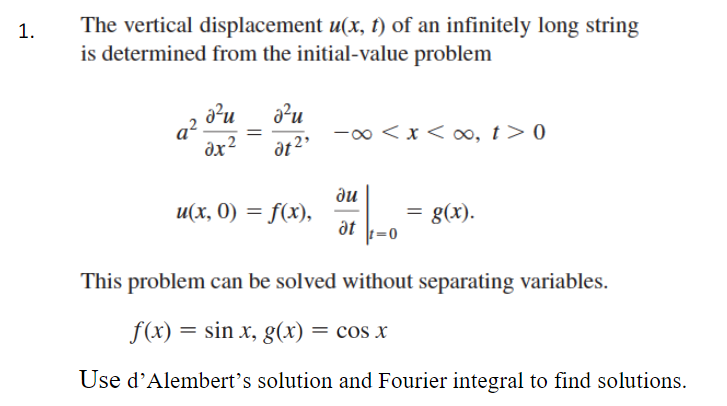

clear
clf
clc
syms u(x,t) u_t(x,t) f(x) g(x) a t x phi(x) psi(x) c s w U(w,t) F(w) G(w) Y(t) cf A(w) B(w) pi i
assume(t,"positive")

WaveEq = (a^2)*diff(u,x,2) == diff(u,t,2)

$$WaveEq(x, t) = a^{2}\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)=\frac{\partial^{2}}{\partial t^{2}}u\left(x,t\right)$$

WEq1 = diff(u,x,2);
WEq2 = diff(u,t,2);

In0 = u(x,0) == sin(x); Int0 = u_t(x,0) == cos(x);

phi(x) = sin(x);
psi(x) = cos(x);

d'Alembeart's formmula for homogeneous equation

C = c; T = t;
w1 = (1/2)*(phi(x-c*t)+phi(x+c*t))

$$w1 = \frac{\sin\left(x+c\,t\right)}{2}+\frac{\sin\left(x-c\,t\right)}{2}$$

w2 = (1/2*c)*int(psi,x,[x-c*t x+c*t])

$$w2 = c\,\sin\left(c\,t\right)\,\cos\left(x\right)$$

u(x,t) = simplify(w1 + w2);
u(x,t) = subs(u(x,t),[c t],[C T])

$$u(x, t) = \cos\left(c\,t\right)\,\sin\left(x\right)+c\,\sin\left(c\,t\right)\,\cos\left(x\right)$$

integral fourier part

u(x,t) = subs(u(x,t),t,w*t)

$$u(x, t) = \cos\left(c\,t\,w\right)\,\sin\left(x\right)+c\,\sin\left(c\,t\,w\right)\,\cos\left(x\right)$$

u(w,t) = subs(u(x,t),[sin(x) c*cos(x)],[A(w) B(w)])

$$u(w, t) = \cos\left(c\,t\,w\right)\,A\left(w\right)+\sin\left(c\,t\,w\right)\,B\left(w\right)$$

u(w,t) = subs(u(w,t),[A(w) B(w)],[f(w) g(w)])

$$u(w, t) = \cos\left(c\,t\,w\right)\,f\left(w\right)+\sin\left(c\,t\,w\right)\,g\left(w\right)$$

u(x,t) = 1/sqrt(2*pi)*int(u(w,t)*exp(i*w*x),w,[-inf inf])

$$u(x, t) = \frac{\sqrt{2}\,\int_{-\infty }^{\infty }{\mathrm{e}}^{i\,w\,x}\,\left(\cos\left(c\,t\,w\right)\,f\left(w\right)+\sin\left(c\,t\,w\right)\,g\left(w\right)\right)\mathrm{d}w}{2\,\sqrt{\pi }}$$

u(x,t) = subs(u(x,t),[cos(c*t*w)*f(w) sin(c*t*w)*g(w)],[sin(w) cos(w)]);

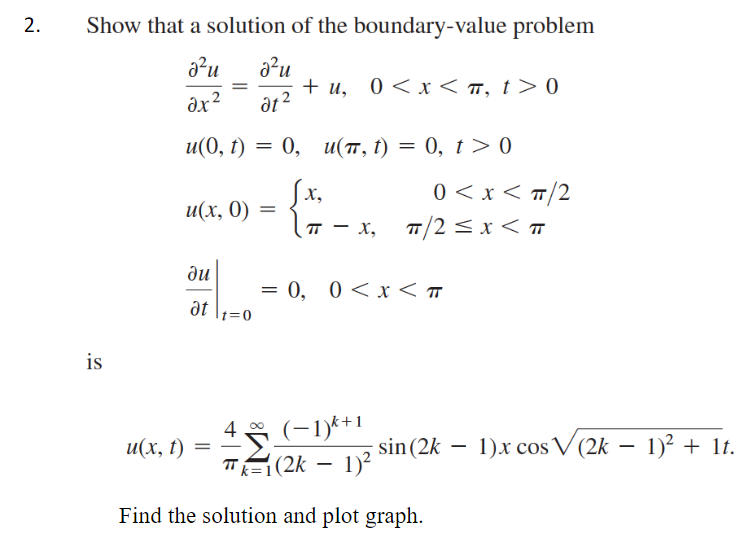

clear
clf
clc
syms x c A L pi w(x,t) phi(x) u(x,t) t uu k U(x,t) i
assume([L c],"positive")
assume(t,"positive")

WaveEq = diff(u,x,2) == diff(u,t,2) + u

$$WaveEq(x, t) = \frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)=\frac{\partial^{2}}{\partial t^{2}}u\left(x,t\right)+u\left(x,t\right)$$

BC0 = u(0,t) == 0; BCL = u(pi,t) == 0;

case 0 < x < pi/2

t0 = u(x,0) == x

$$t0 = u\left(x,0\right)=x$$

Dt = diff(u,t);
Dt0 = Dt(x,0) == 0

$$Dt0 = \left({\left(\frac{\partial }{\partial t}u\left(x,t\right)\right)|}_{t=0}\right)=0$$

syms T(t) X(x)
SepVar = subs(WaveEq,u(x,t),X(x)*T(t))

$$SepVar(x, t) = T\left(t\right)\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)=X\left(x\right)\,\frac{\partial^{2}}{\partial t^{2}}T\left(t\right)+T\left(t\right)\,X\left(x\right)$$

BC0 = subs(BC0,u(0,t),X(0))

$$BC0 = X\left(0\right)=0$$

BCL = subs(BCL,u(pi,t),X(pi))

$$BCL = X\left(\pi \right)=0$$

T0 = subs(t0,u(x,0),T(0))

$$T0 = T\left(0\right)=x$$

DT = diff(T,t);
DT0 = subs(Dt0,Dt(x,0),DT(0))

$$DT0 = \left({\left(\frac{\partial }{\partial t}T\left(t\right)\right)|}_{t=0}\right)=0$$

SepVar = SepVar/(X(x)*T(t))

$$SepVar(x, t) = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=\frac{X\left(x\right)\,\frac{\partial^{2}}{\partial t^{2}}T\left(t\right)+T\left(t\right)\,X\left(x\right)}{T\left(t\right)\,X\left(x\right)}$$

syms lambda
assume(lambda,"positive")
var = children(SepVar);
eqX = var(1) == -lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

eqT = var(2) == -lambda^2

$$eqT = \frac{X\left(x\right)\,\frac{\partial^{2}}{\partial t^{2}}T\left(t\right)+T\left(t\right)\,X\left(x\right)}{T\left(t\right)\,X\left(x\right)}=-\lambda^{2}$$

X(x) = dsolve(eqX,BC0)

$$X(x) = -C_{1}\,\sin\left(\lambda \,x\right)$$

T(t) = dsolve(eqT,DT0)

$$T(t) = C_{1}\,\cos\left(t\,\sqrt{\lambda^{2}+1}\right)$$

constantX = setdiff(symvar(X(x)),sym(['C',x,lambda,c]));
X(x) = subs(-X(x),constantX,sym('C2'))

$$X(x) = C_{2}\,\sin\left(\lambda \,x\right)$$

sln = X(pi) == 0

$$sln = C_{2}\,\sin\left(\lambda \,\pi \right)=0$$

[lambda,parameters,~] = solve(sln,lambda,"ReturnConditions",true)

$$lambda = x$$

$$parameters = x$$

n = sym("n",["integer","positive"]);
lambda = subs(lambda,parameters,n)

$$lambda = n$$

syms A_n ustruct(x,t);
sT(t) = subs(T(t),str2sym({'lambda','C1'}),{lambda,A_n});
sX(x) = subs(X(x),str2sym({'lambda','C2'}),{lambda,1});
ustruct(x,t) = sX(x)*sT(t)

$$ustruct(x, t) = A_{n}\,\sin\left(n\,x\right)\,\cos\left(t\,\sqrt{n^{2}+1}\right)$$

fprintf("----=Fourier part=----")

----=Fourier part=----

f0 = ustruct(x,0)

$$f0 = A_{n}\,\sin\left(n\,x\right)$$

f0 = subs(f0,sym('A_n'),1);
A_n = 2/pi*int(rhs(T0)*f0,x,[0 pi])

$$A\_n = \frac{2\,\left(\sin\left(n\,\pi \right)-n\,\pi \,\cos\left(n\,\pi \right)\right)}{n^{2}\,\pi }$$

u = subs(ustruct,'A_n',1)*A_n

$$u(x, t) = \frac{2\,\sin\left(n\,x\right)\,\cos\left(t\,\sqrt{n^{2}+1}\right)\,\left(\sin\left(n\,\pi \right)-n\,\pi \,\cos\left(n\,\pi \right)\right)}{n^{2}\,\pi }$$

u = subs(u,[sin(n*pi) cos(n*pi)],[0 1])

$$u(x, t) = -\frac{2\,\sin\left(n\,x\right)\,\cos\left(t\,\sqrt{n^{2}+1}\right)}{n}$$

u = subs(u,n,2*k-1)

$$u(x, t) = -\frac{2\,\sin\left(x\,\left(2\,k-1\right)\right)\,\cos\left(t\,\sqrt{{\left(2\,k-1\right)}^{2}+1}\right)}{2\,k-1}$$

case pi/2 < x < pi

t0z = U(x,0) == pi - x

$$t0z = U\left(x,0\right)=\pi -x$$

T0z = subs(t0,U(x,0),T(0))

$$T0z = u\left(x,0\right)=x$$

f0z = ustruct(x,0)

$$f0z = A_{n}\,\sin\left(n\,x\right)$$

f0z = subs(f0z,sym('A_n'),1);
A_nz = 2/pi*int(rhs(T0z)*f0z,x,[0 pi]);
uz = subs(ustruct,'A_n',1)*A_nz;
uz = subs(uz,[sin(n*pi) cos(n*pi)],[0 1]);
uz = subs(uz,n,2*k-1);
uz = (subs(uz,sin(x*(2*k-1)),((-1)^(k-1))))/pi

$$uz(x, t) = -\frac{2\,{\left(-1\right)}^{k-1}\,\cos\left(t\,\sqrt{{\left(2\,k-1\right)}^{2}+1}\right)}{\pi \,\left(2\,k-1\right)}$$

uz = subs(uz,cos(t*sqrt(((2*k-1)^2)+1)),1)

$$uz(x, t) = -\frac{2\,{\left(-1\right)}^{k-1}}{\pi \,\left(2\,k-1\right)}$$

u(x,t) = simplify(u*uz)

$$u(x, t) = \frac{4\,{\left(-1\right)}^{k+1}\,\sin\left(x\,\left(2\,k-1\right)\right)\,\cos\left(t\,\sqrt{{\left(2\,k-1\right)}^{2}+1}\right)}{\pi \,{\left(2\,k-1\right)}^{2}}$$

u(x,t) = subs(u(x,t),pi,3.14)

$$u(x, t) = \frac{200\,{\left(-1\right)}^{k+1}\,\sin\left(x\,\left(2\,k-1\right)\right)\,\cos\left(t\,\sqrt{{\left(2\,k-1\right)}^{2}+1}\right)}{157\,{\left(2\,k-1\right)}^{2}}$$

u(x,t) = symsum(u(x,t),k,1,inf)

$$u(x, t) = \frac{200\,\left(\sum_{k=1}^{\infty }\frac{{\left(-1\right)}^{k+1}\,\sin\left(x\,\left(2\,k-1\right)\right)\,\cos\left(t\,\sqrt{{\left(2\,k-1\right)}^{2}+1}\right)}{{\left(2\,k-1\right)}^{2}}\right)}{157}$$

i = 3

i = 3

Time = 15

Time = 15

u(x,t) = subs(u(x,t),inf,i)

$$u(x, t) = \frac{8\,\sin\left(5\,x\right)\,\cos\left(\sqrt{26}\,t\right)}{157}-\frac{200\,\sin\left(3\,x\right)\,\cos\left(\sqrt{10}\,t\right)}{1413}+\frac{200\,\cos\left(\sqrt{2}\,t\right)\,\sin\left(x\right)}{157}$$

u(x,t) = subs(u(x,t),t,Time)

$$u(x, t) = \frac{200\,\cos\left(15\,\sqrt{2}\right)\,\sin\left(x\right)}{157}-\frac{200\,\cos\left(15\,\sqrt{10}\right)\,\sin\left(3\,x\right)}{1413}+\frac{8\,\cos\left(15\,\sqrt{26}\right)\,\sin\left(5\,x\right)}{157}$$

2D plot

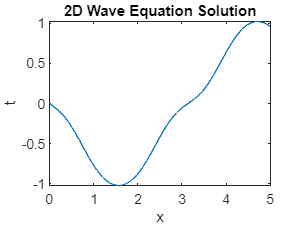

fplot(@(x) u(x,t),[0 5])
xlabel('x');
ylabel('t');
title('2D Wave Equation Solution');

3D plot

% Plot the function as a 3D surface
Distance = 9

Distance = 9

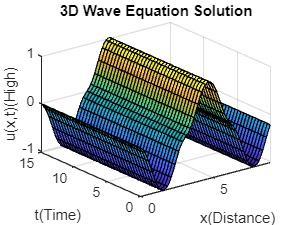

FinalPlot = @(x,t) u(x,t);
fsurf(u(x,t),[0 Distance 0 Time]);
% Add labels and a title
xlabel('x(Distance)');
ylabel('t(Time)');
zlabel('u(x,t)(High)');
title('3D Wave Equation Solution');

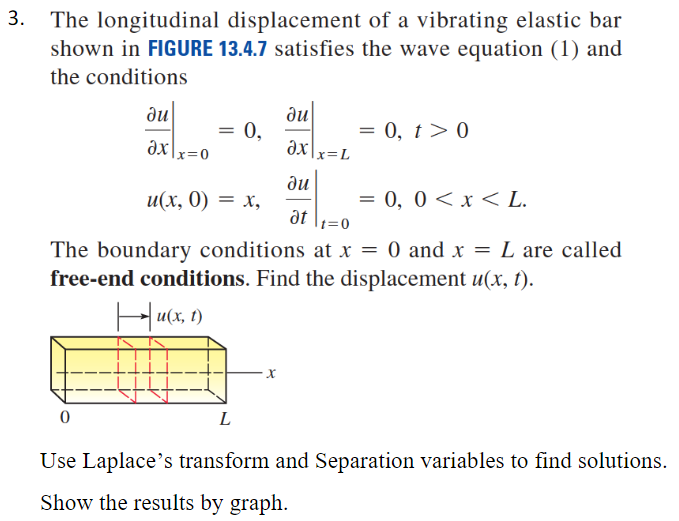

clear; clf; clc;
syms x t L c s u(x,t) X(x) T(t) n

WaveEq = diff(u,t,2) == (c^2)*diff(u,x,2)

$$WaveEq(x, t) = \frac{\partial^{2}}{\partial t^{2}}u\left(x,t\right)=c^{2}\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)$$

%BC0 = u(0,t) == 0; BCL = u(L,t) == 0;

Conditions

t0 = u(x,0) == x;
Dt = diff(u,t); Dt0 = Dt(x,0) == 0;
Dx = diff(u,x); Dx0 = Dx(0,t) == 0; DxL = Dx(L,t) == 0;
DX0 = subs(Dx0,Dx(0,t),X(0)); DXL = subs(DxL,Dx(L,t),X(L)); DT0 = subs(Dt0,Dt(x,0),T(0));
%u(x,t) = X(x)*T(t)

Seperation

SepVar = subs(WaveEq,u(x,t),X(x)*T(t))

$$SepVar(x, t) = X\left(x\right)\,\frac{\partial^{2}}{\partial t^{2}}T\left(t\right)=c^{2}\,T\left(t\right)\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)$$

SepVar = SepVar/(X(x)*T(t))

$$SepVar(x, t) = \frac{\frac{\partial^{2}}{\partial t^{2}}T\left(t\right)}{T\left(t\right)}=\frac{c^{2}\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}$$

syms lambda
assume(lambda,"positive")
var = children(SepVar);
eqT = var(1) == -lambda

$$eqT = \frac{\frac{\partial^{2}}{\partial t^{2}}T\left(t\right)}{T\left(t\right)}=-\lambda$$

reqT = rhs(eqT)*c^2

$$reqT = -c^{2}\,\lambda$$

eqX = var(2) == -lambda

$$eqX = \frac{c^{2}\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda$$

eqT = subs(eqT,lambda,-reqT)

$$eqT = \frac{\frac{\partial^{2}}{\partial t^{2}}T\left(t\right)}{T\left(t\right)}=-c^{2}\,\lambda$$

eqX = subs(eqX,c^2,1)

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda$$

eqT = eqT*T(t)

$$eqT = \frac{\partial^{2}}{\partial t^{2}}T\left(t\right)=-c^{2}\,\lambda \,T\left(t\right)$$

eqX = eqX*X(x)

$$eqX = \frac{\partial^{2}}{\partial x^{2}}X\left(x\right)=-\lambda \,X\left(x\right)$$

EqT = rhs(eqT) + lhs(eqT) == 0

$$EqT = \frac{\partial^{2}}{\partial t^{2}}T\left(t\right)-c^{2}\,\lambda \,T\left(t\right)=0$$

EqX = rhs(eqX) + lhs(eqX) == 0

$$EqX = \frac{\partial^{2}}{\partial x^{2}}X\left(x\right)-\lambda \,X\left(x\right)=0$$

case I : λ = 0

EqXI = subs(EqX,lambda,0)

$$EqXI = \frac{\partial^{2}}{\partial x^{2}}X\left(x\right)=0$$

XI = dsolve(EqXI);
constantXI = setdiff(symvar(XI),sym(['C2',x]));
XI = subs(XI,constantXI,sym('0'))

$$XI = C_{2}$$

EqTI = subs(EqT,lambda,0)

$$EqTI = \frac{\partial^{2}}{\partial t^{2}}T\left(t\right)=0$$

TI = dsolve(EqTI);
constantTI = setdiff(symvar(TI),sym(['C2',t]));
TI = subs(TI,constantTI,sym('0'));
constantTI2 = setdiff(symvar(TI),sym(t));
TI = subs(TI,constantTI2,sym('C3'))

$$TI = C_{3}$$

syms u_0I(x,t)
u_0I(x,t) = simplify(XI*TI)

$$u\_0I(x, t) = C_{2}\,C_{3}$$

UI = u_0I == subs(u_0I(x,t),[sym('C2') sym('C3')],[sym('C') 1])

$$UI(x, t) = C_{2}\,C_{3}=C$$

case II : λ = α^2 > 0

syms alpha
EqXII = subs(EqX,lambda,alpha^2)

$$EqXII = \frac{\partial^{2}}{\partial x^{2}}X\left(x\right)-\alpha^{2}\,X\left(x\right)=0$$

XII = dsolve(EqXII)

$$XII = C_{1}\,{\mathrm{e}}^{\alpha \,x}+C_{2}\,{\mathrm{e}}^{-\alpha \,x}$$

XII = subs(XII,exp(alpha*x),cosh(alpha*x))

$$XII = C_{1}\,\cosh\left(\alpha \,x\right)+\frac{C_{2}}{\cosh\left(\alpha \,x\right)}$$

XII = subs(XII,[sym('C2')/cosh(alpha*x) sym('C1')],[sym('C5')*sinh(alpha*x) sym('C4')])

$$XII = C_{4}\,\cosh\left(\alpha \,x\right)+C_{5}\,\sinh\left(\alpha \,x\right)$$

eqcondXII = diff(X,x) == diff(XII,x)

$$eqcondXII(x) = \frac{\partial }{\partial x}X\left(x\right)=C_{5}\,\alpha \,\cosh\left(\alpha \,x\right)+C_{4}\,\alpha \,\sinh\left(\alpha \,x\right)$$

condXII = subs(eqcondXII,x,0);
condXII = subs(condXII,sym('C5'),1)

$$condXII(x) = \left({\left(\frac{\partial }{\partial x}X\left(x\right)\right)|}_{x=0}\right)=\alpha$$

condXII = subs(condXII,[diff(X,x) alpha],[0 sym('C5')*alpha])

$$condXII(x) = 0=C_{5}\,\alpha$$

condXII = subs(condXII,alpha,1)

$$condXII(x) = 0=C_{5}$$

eqcondXII = subs(eqcondXII,sym('C5')*alpha*cosh(alpha*x),0)

$$eqcondXII(x) = \frac{\partial }{\partial x}X\left(x\right)=C_{4}\,\alpha \,\sinh\left(\alpha \,x\right)$$

eqcondXII = subs(eqcondXII,x,L)

$$eqcondXII(x) = \frac{\partial }{\partial L}X\left(L\right)=C_{4}\,\alpha \,\sinh\left(L\,\alpha \right)$$

condLII = rhs(eqcondXII) == 0

$$condLII(x) = C_{4}\,\alpha \,\sinh\left(L\,\alpha \right)=0$$

condLII = solve(condLII,sym('C4'));
eqcondXII = subs(eqcondXII,sym('C4'),condLII)

$$eqcondXII(x) = \frac{\partial }{\partial L}X\left(L\right)=0$$

XII = subs(XII,[sym('C4') sym('C5')],[condLII condLII])

$$XII = 0$$

case III : λ = -α^2 < 0

syms pi A_n
EqXIII = subs(EqX,lambda,-alpha^2)

$$EqXIII = \frac{\partial^{2}}{\partial x^{2}}X\left(x\right)+X\left(x\right)\,\alpha^{2}=0$$

XIII = dsolve(EqXIII);
XIII = subs(XIII,[sym('C2')*exp(alpha*x*1i) sym('C1')*exp(-alpha*x*1i)],[sym('C6')*cos(alpha*x) sym('C7')*sin(alpha*x)])

$$XIII = C_{6}\,\cos\left(\alpha \,x\right)+C_{7}\,\sin\left(\alpha \,x\right)$$

eqcondXIII = diff(X,x) == diff(XIII,x)

$$eqcondXIII(x) = \frac{\partial }{\partial x}X\left(x\right)=C_{7}\,\alpha \,\cos\left(\alpha \,x\right)-C_{6}\,\alpha \,\sin\left(\alpha \,x\right)$$

condXIII = subs(eqcondXIII,x,0);
condXIII = subs(condXIII,sym('C7'),1)

$$condXIII(x) = \left({\left(\frac{\partial }{\partial x}X\left(x\right)\right)|}_{x=0}\right)=\alpha$$

condXIII = subs(condXIII,[diff(X,x) alpha],[0 sym('C7')*alpha])

$$condXIII(x) = 0=C_{7}\,\alpha$$

condXIII = solve(condXIII,sym('C7'));
eqcondXIII = subs(eqcondXIII,sym('C7'),condXIII)

$$eqcondXIII(x) = \frac{\partial }{\partial x}X\left(x\right)=-C_{6}\,\alpha \,\sin\left(\alpha \,x\right)$$

XIII = dsolve(eqcondXIII)

$$XIII = C_{1}+C_{6}\,\cos\left(\alpha \,x\right)$$

XIII = subs(XIII,sym('C1'),0)

$$XIII = C_{6}\,\cos\left(\alpha \,x\right)$$

alpha_n = n*pi/L

$$alpha\_n = \frac{n\,\pi }{L}$$

XnIII = subs(XIII,alpha,alpha_n)

$$XnIII = C_{6}\,\cos\left(\frac{n\,\pi \,x}{L}\right)$$


EqTIII = subs(EqT,lambda,-alpha^2)

$$EqTIII = \frac{\partial^{2}}{\partial t^{2}}T\left(t\right)+T\left(t\right)\,\alpha^{2}\,c^{2}=0$$

TIII = dsolve(EqTIII)

$$TIII = C_{1}\,{\mathrm{e}}^{-\alpha \,c\,t\,\mathrm{i}}+C_{2}\,{\mathrm{e}}^{\alpha \,c\,t\,\mathrm{i}}$$

TIII = subs(TIII,[sym('C2')*exp(alpha*1i*t*c) sym('C1')*exp(-alpha*1i*t*c)],[sym('C8')*cos(alpha*c*t) sym('C9')*sin(alpha*c*t)])

$$TIII = C_{8}\,\cos\left(\alpha \,c\,t\right)+C_{9}\,\sin\left(\alpha \,c\,t\right)$$

eqcondTIII = diff(T,t) == diff(TIII,t)

$$eqcondTIII(t) = \frac{\partial }{\partial t}T\left(t\right)=C_{9}\,\alpha \,c\,\cos\left(\alpha \,c\,t\right)-C_{8}\,\alpha \,c\,\sin\left(\alpha \,c\,t\right)$$

condTIII = subs(eqcondTIII,t,0)

$$condTIII(t) = \left({\left(\frac{\partial }{\partial t}T\left(t\right)\right)|}_{t=0}\right)=C_{9}\,\alpha \,c$$

condTIII = rhs(condTIII) == 0

$$condTIII(t) = C_{9}\,\alpha \,c=0$$

Constant9 = solve(condTIII,sym('C9'))

$$Constant9 = 0$$

TnIII = subs(TIII,sym('C9'),Constant9)

$$TnIII = C_{8}\,\cos\left(\alpha \,c\,t\right)$$

TnIII = subs(TnIII,alpha,alpha_n)

$$TnIII = C_{8}\,\cos\left(\frac{c\,n\,\pi \,t}{L}\right)$$

UIII = simplify(XnIII*TnIII);
ConstantIII = setdiff(symvar(UIII),sym([x,t,L,c,n,pi]));
UIII = subs(UIII,[ConstantIII(1) ConstantIII(2)],[A_n 1])

$$UIII = A_{n}\,\cos\left(\frac{c\,n\,\pi \,t}{L}\right)\,\cos\left(\frac{n\,\pi \,x}{L}\right)$$

syms A_0 A(x)
i = 3;
ValueL = 0.2;
C = 1;
UIII = subs(UIII,A_n,A(n));
dispu(x,t) = A_0/2 + symsum(UIII,n,1,inf)

$$dispu(x, t) = \frac{A_{0}}{2}+\left(\sum_{n=1}^{\infty }\cos\left(\frac{c\,n\,\pi \,t}{L}\right)\,A\left(n\right)\,\cos\left(\frac{n\,\pi \,x}{L}\right)\right)$$

Ax0 = 2/L*int(x,x,[0 L])

$$Ax0 = L$$

Axn = 2/L*int(x*cos(n*pi*x/L),x,[0 L])

$$Axn = -\frac{2\,L\,\left(2\,{\sin\left(\frac{n\,\pi }{2}\right)}^{2}-n\,\pi \,\sin\left(n\,\pi \right)\right)}{n^{2}\,\pi^{2}}$$

Axn = subs(Axn,2*(sin(n*pi/2)^2)-n*pi*sin(n*pi),-((-1)^n-1))

$$Axn = \frac{2\,L\,\left({\left(-1\right)}^{n}-1\right)}{n^{2}\,\pi^{2}}$$

UIII = subs(UIII,[A_0 A(n)],[Ax0 Axn])

$$UIII = \frac{2\,L\,\cos\left(\frac{c\,n\,\pi \,t}{L}\right)\,\cos\left(\frac{n\,\pi \,x}{L}\right)\,\left({\left(-1\right)}^{n}-1\right)}{n^{2}\,\pi^{2}}$$

UIII = subs(UIII,{pi,L,c},{3.14,ValueL,C})

$$UIII = \frac{1000\,\cos\left(\frac{157\,n\,t}{10}\right)\,\cos\left(\frac{157\,n\,x}{10}\right)\,\left({\left(-1\right)}^{n}-1\right)}{24649\,n^{2}}$$

u(x,t) = symsum(UIII,n,1,i)

$$u(x, t) = -\frac{2000\,\cos\left(\frac{157\,t}{10}\right)\,\cos\left(\frac{157\,x}{10}\right)}{24649}-\frac{2000\,\cos\left(\frac{471\,t}{10}\right)\,\cos\left(\frac{471\,x}{10}\right)}{221841}$$

% Plot the function as a 3D surface
NeDistance = -5

NeDistance = -5

PoDistance = 5;
Time = 5

Time = 5

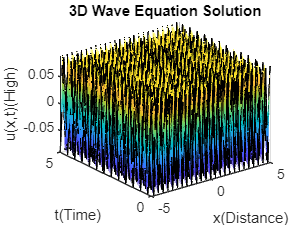

FinalPlot = @(x,t) u(x,t);
fsurf(u(x,t),[NeDistance PoDistance 0 Time]);
% Add labels and a title
xlabel('x(Distance)');
ylabel('t(Time)');
zlabel('u(x,t)(High)');
title('3D Wave Equation Solution');

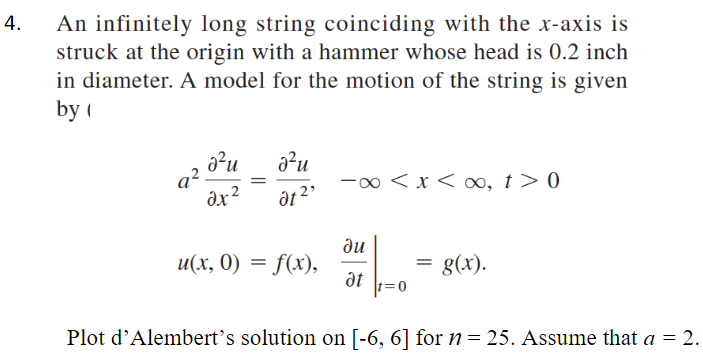

clear
clf
clc
syms u(x,t) x t f(x) g(x) a n c
assume(t,"positive")

Dt(x,t) = diff(u,t); D2t(x,t) = diff(Dt,t);
Dx(x,t) = diff(u,x); D2x(x,t) = diff(Dx,x);
WaveEq = (a^2)*D2x == D2t

$$WaveEq(x, t) = a^{2}\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)=\frac{\partial^{2}}{\partial t^{2}}u\left(x,t\right)$$

WaveEq = subs(WaveEq,a,2)

$$WaveEq(x, t) = 4\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)=\frac{\partial^{2}}{\partial t^{2}}u\left(x,t\right)$$

WEq1 = D2x;
WEq2 = D2t;

fprintf('Fill your f(x) =')

Fill your f(x) =

phi(x) = sin(x)

$$phi(x) = \sin\left(x\right)$$

fprintf('Fill your g(x) =')

Fill your g(x) =

psi(x) = cos(x)

$$psi(x) = \cos\left(x\right)$$

d'Alembeart's formmula for homogeneous equation

C = 25; T = 3;
w1 = (1/2)*(phi(x-c*t)+phi(x+c*t))

$$w1 = \frac{\sin\left(x+c\,t\right)}{2}+\frac{\sin\left(x-c\,t\right)}{2}$$

w2 = (1/2*c)*int(psi,x,[x-c*t x+c*t])

$$w2 = c\,\sin\left(c\,t\right)\,\cos\left(x\right)$$

u(x,t) = simplify(w1 + w2);
u(x,t) = subs(u(x,t),[c t],[C T])

$$u(x, t) = \cos\left(75\right)\,\sin\left(x\right)+25\,\sin\left(75\right)\,\cos\left(x\right)$$

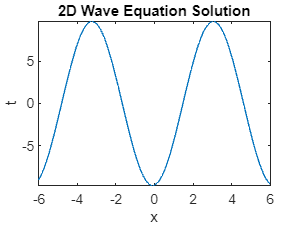

fplot(@(x) u(x,t),[-6 6])
xlabel('x');
ylabel('t');
title('2D Wave Equation Solution');

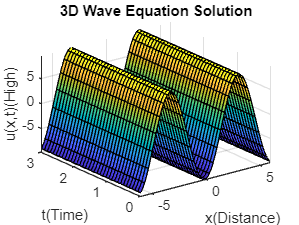

FinalPlot = @(x,t) u(x,t);
fsurf(u(x,t),[-6 6 0 T]);
xlabel('x(Distance)');
ylabel('t(Time)');
zlabel('u(x,t)(High)');
title('3D Wave Equation Solution');

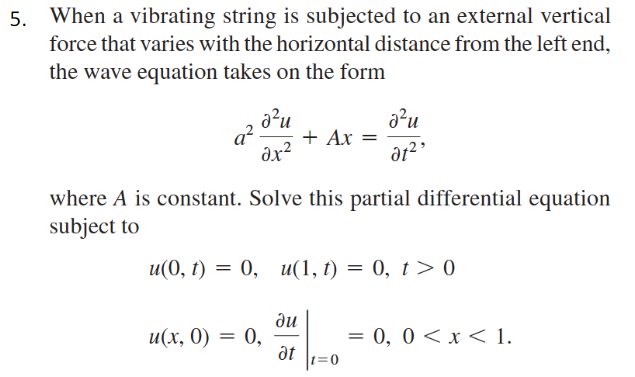

clear
clf
clc
syms x c A L pi w(x,t) phi(x) u(x,t) t uu k U(x,t) i T(t) X(x)
assume([L c],"positive")
assume(t,"positive")

WaveEq = diff(u,x,2) == diff(u,t,2) + A*X(x)

$$WaveEq(x, t) = \frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)=\frac{\partial^{2}}{\partial t^{2}}u\left(x,t\right)+A\,X\left(x\right)$$

BC0 = u(0,t) == 0; BCL = u(1,t) == 0;
t0 = u(x,0) == x

$$t0 = u\left(x,0\right)=x$$

Dt = diff(u,t);
Dt0 = Dt(x,0) == 0

$$Dt0 = \left({\left(\frac{\partial }{\partial t}u\left(x,t\right)\right)|}_{t=0}\right)=0$$

SepVar = subs(WaveEq,u(x,t),X(x)*T(t))

$$SepVar(x, t) = T\left(t\right)\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)=X\left(x\right)\,\frac{\partial^{2}}{\partial t^{2}}T\left(t\right)+A\,X\left(x\right)$$

BC0 = subs(BC0,u(0,t),X(0))

$$BC0 = X\left(0\right)=0$$

BCL = subs(BCL,u(pi,t),X(pi))

$$BCL = u\left(1,t\right)=0$$

T0 = subs(t0,u(x,0),T(0))

$$T0 = T\left(0\right)=x$$

DT = diff(T,t);
DT0 = subs(Dt0,Dt(x,0),DT(0))

$$DT0 = \left({\left(\frac{\partial }{\partial t}T\left(t\right)\right)|}_{t=0}\right)=0$$

SepVar = SepVar/(X(x)*T(t))

$$SepVar(x, t) = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=\frac{X\left(x\right)\,\frac{\partial^{2}}{\partial t^{2}}T\left(t\right)+A\,X\left(x\right)}{T\left(t\right)\,X\left(x\right)}$$

syms lambda
assume(lambda,"positive")
var = children(SepVar);
eqX = var(1) == -lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

eqT = var(2) == -lambda^2

$$eqT = \frac{X\left(x\right)\,\frac{\partial^{2}}{\partial t^{2}}T\left(t\right)+A\,X\left(x\right)}{T\left(t\right)\,X\left(x\right)}=-\lambda^{2}$$

X(x) = dsolve(eqX,BC0)

$$X(x) = -C_{1}\,\sin\left(\lambda \,x\right)$$

T(t) = dsolve(eqT,DT0)

$$T(t) = C_{1}\,\cos\left(\lambda \,t\right)-\frac{A}{\lambda^{2}}$$

constantX = setdiff(symvar(X(x)),sym(['C',x,lambda,c]));
X(x) = subs(-X(x),constantX,sym('C2'))

$$X(x) = C_{2}\,\sin\left(\lambda \,x\right)$$

sln = X(pi) == 0

$$sln = C_{2}\,\sin\left(\lambda \,\pi \right)=0$$

[lambda,parameters,~] = solve(sln,lambda,"ReturnConditions",true)

$$lambda = x$$

$$parameters = x$$

n = sym("n",["integer","positive"]);
lambda = subs(lambda,parameters,n)

$$lambda = n$$

syms A_n ustruct(x,t);
sT(t) = subs(T(t),str2sym({'lambda','C1'}),{lambda,A_n});
sX(x) = subs(X(x),str2sym({'lambda','C2'}),{lambda,1});
ustruct(x,t) = sX(x)*sT(t)

$$ustruct(x, t) = \sin\left(n\,x\right)\,\left(A_{n}\,\cos\left(n\,t\right)-\frac{A}{n^{2}}\right)$$

fprintf("----=Fourier part=----")

----=Fourier part=----

f0 = ustruct(x,0)

$$f0 = \sin\left(n\,x\right)\,\left(A_{n}-\frac{A}{n^{2}}\right)$$

f0 = subs(f0,sym('A_n'),1);
A_n = 2/pi*int(rhs(T0)*f0,x,[0 pi])

$$A\_n = -\frac{2\,\left(A-n^{2}\right)\,\left(\sin\left(n\,\pi \right)-n\,\pi \,\cos\left(n\,\pi \right)\right)}{n^{4}\,\pi }$$

u = subs(ustruct,'A_n',1)*A_n

$$u(x, t) = -\frac{2\,\sin\left(n\,x\right)\,\left(\cos\left(n\,t\right)-\frac{A}{n^{2}}\right)\,\left(A-n^{2}\right)\,\left(\sin\left(n\,\pi \right)-n\,\pi \,\cos\left(n\,\pi \right)\right)}{n^{4}\,\pi }$$

u = subs(u,[sin(n*pi) cos(n*pi)],[0 1])

$$u(x, t) = \frac{2\,\sin\left(n\,x\right)\,\left(\cos\left(n\,t\right)-\frac{A}{n^{2}}\right)\,\left(A-n^{2}\right)}{n^{3}}$$

u = subs(u,n,2*k-1)

$$u(x, t) = \frac{2\,\sin\left(x\,\left(2\,k-1\right)\right)\,\left(A-{\left(2\,k-1\right)}^{2}\right)\,\left(\cos\left(t\,\left(2\,k-1\right)\right)-\frac{A}{{\left(2\,k-1\right)}^{2}}\right)}{{\left(2\,k-1\right)}^{3}}$$

i = 3

i = 3

u(x,t) = symsum(u(x,t),k,1,i)

$$u(x, t) = -2\,\sin\left(x\right)\,\left(A-1\right)\,\left(A-\cos\left(t\right)\right)-\frac{2\,\sin\left(3\,x\right)\,\left(\frac{A}{9}-\cos\left(3\,t\right)\right)\,\left(A-9\right)}{27}-\frac{2\,\sin\left(5\,x\right)\,\left(\frac{A}{25}-\cos\left(5\,t\right)\right)\,\left(A-25\right)}{125}$$

Time = 15

Time = 15

u(x,t) = subs(u(x,t),t,Time)

$$u(x, t) = -\frac{2\,\sin\left(3\,x\right)\,\left(A-9\right)\,\left(\frac{A}{9}-\cos\left(45\right)\right)}{27}-\frac{2\,\sin\left(5\,x\right)\,\left(A-25\right)\,\left(\frac{A}{25}-\cos\left(75\right)\right)}{125}-2\,\sin\left(x\right)\,\left(A-\cos\left(15\right)\right)\,\left(A-1\right)$$

3D plot

% Plot the function as a 3D surface
Distance = 9

Distance = 9

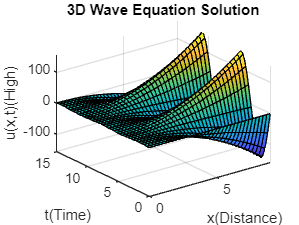

FinalPlot = @(x,t) u(x,t);
fsurf(u(x,t),[0 Distance 0 Time]);
% Add labels and a title
xlabel('x(Distance)');
ylabel('t(Time)');
zlabel('u(x,t)(High)');
title('3D Wave Equation Solution');

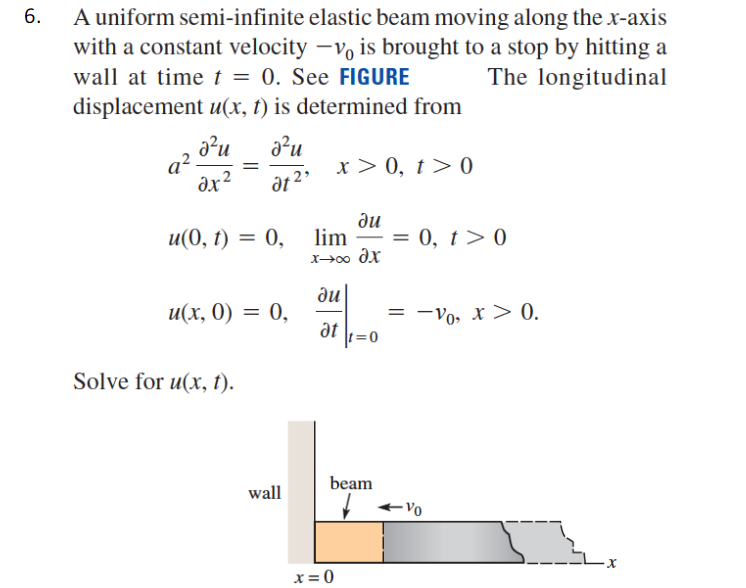

clc; clf; clearvars;
syms u(x,t) a U(x,s) v_0 U_c(x,s) U_p(x,s) m x

WaveEq = a^2*diff(u,x,2) == diff(u,t,2)

$$WaveEq(x, t) = a^{2}\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)=\frac{\partial^{2}}{\partial t^{2}}u\left(x,t\right)$$

Dt = diff(u,t);
eqn = laplace(WaveEq)

$$eqn(x) = a^{2}\,\mathrm{laplace}\left(\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right),t,s\right)=s^{2}\,\mathrm{laplace}\left(u\left(x,t\right),t,s\right)-s\,u\left(x,0\right)-\left({\left(\frac{\partial }{\partial t}u\left(x,t\right)\right)|}_{t=0}\right)$$

eqn = subs(eqn,{laplace(u(x,t),t,s),laplace(diff(u,x,2),t,s)},{U(x,s),diff(U,s,2)})

$$eqn(x) = a^{2}\,\frac{\partial^{2}}{\partial s^{2}}U\left(x,s\right)=s^{2}\,U\left(x,s\right)-s\,u\left(x,0\right)-\left({\left(\frac{\partial }{\partial t}u\left(x,t\right)\right)|}_{t=0}\right)$$

eqn = subs(eqn,{u(x,0),Dt(x,0)},{0,-v_0})

$$eqn(x) = a^{2}\,\frac{\partial^{2}}{\partial s^{2}}U\left(x,s\right)=v_{0}+s^{2}\,U\left(x,s\right)$$

Find Uc (homogeneous)

D2U = diff(U,s,2) 

$$D2U(x, s) = \frac{\partial^{2}}{\partial s^{2}}U\left(x,s\right)$$

homo_eqn = subs(eqn,v_0,0)

$$homo\_eqn(x) = a^{2}\,\frac{\partial^{2}}{\partial s^{2}}U\left(x,s\right)=s^{2}\,U\left(x,s\right)$$

homo_eqn = subs(homo_eqn,{D2U,U(x,s)},{m^2,1})

$$homo\_eqn(x) = a^{2}\,m^{2}=s^{2}$$

m_constant = solve(homo_eqn,m)

$$m\_constant = \left(\begin{array}{c} \frac{s}{a}\\ -\frac{s}{a} \end{array}\right)$$

syms C1 C2
homo_eqn = U_c == C1*exp(m_constant(1)*x) + C2*exp(m_constant(2)*x)

$$homo\_eqn(x, s) = U_{c}\left(x,s\right)=C_{1}\,{\mathrm{e}}^{\frac{s\,x}{a}}+C_{2}\,{\mathrm{e}}^{-\frac{s\,x}{a}}$$

Find Up (nonhomogeneous)

syms K
IU_p = K;
D2K = subs(D2U,U,K)

$$D2K(x, s) = 0$$

nonh_eqn = subs(eqn,{D2U U},{D2K IU_p})

$$nonh\_eqn(x) = 0=K\,s^{2}+v_{0}$$

K_constant = solve(nonh_eqn,K)

$$K\_constant = -\frac{v_{0}}{s^{2}}$$

nonh_eqn = U_p == K_constant

$$nonh\_eqn(x, s) = U_{p}\left(x,s\right)=-\frac{v_{0}}{s^{2}}$$

U(x,s) = U_c + U_p

$$U(x, s) = U_{c}\left(x,s\right)+U_{p}\left(x,s\right)$$

U(x,s) = subs(U,{U_c,U_p},{homo_eqn nonh_eqn})

$$U(x, s) = U_{c}\left(x,s\right)+U_{p}\left(x,s\right)=C_{1}\,{\mathrm{e}}^{\frac{s\,x}{a}}+C_{2}\,{\mathrm{e}}^{-\frac{s\,x}{a}}-\frac{v_{0}}{s^{2}}$$

syms limit
Condx0 = 0;
limxCondUx0 = 0;
eqn_R(x,s) = rhs(U(x,s))

$$eqn\_R(x, s) = C_{1}\,{\mathrm{e}}^{\frac{s\,x}{a}}+C_{2}\,{\mathrm{e}}^{-\frac{s\,x}{a}}-\frac{v_{0}}{s^{2}}$$

eqnx0 = eqn_R(0,s)

$$eqnx0 = C_{1}+C_{2}-\frac{v_{0}}{s^{2}}$$

Eqn = rhs(U)

$$Eqn(x, s) = C_{1}\,{\mathrm{e}}^{\frac{s\,x}{a}}+C_{2}\,{\mathrm{e}}^{-\frac{s\,x}{a}}-\frac{v_{0}}{s^{2}}$$

Eqn = diff(Eqn,x) == 0

$$Eqn(x, s) = \frac{C_{1}\,s\,{\mathrm{e}}^{\frac{s\,x}{a}}}{a}-\frac{C_{2}\,s\,{\mathrm{e}}^{-\frac{s\,x}{a}}}{a}=0$$

Eqn = subs(Eqn,exp(-s*x/a),0)

$$Eqn(x, s) = \frac{C_{1}\,s\,{\mathrm{e}}^{\frac{s\,x}{a}}}{a}=0$$

C1_Constant = solve(Eqn,sym('C1'))

$$C1\_Constant = 0$$

eqnx02 = subs(eqnx0,sym('C1'),C1_Constant)

$$eqnx02 = C_{2}-\frac{v_{0}}{s^{2}}$$

C2_Constant = solve(eqnx02,sym('C2'))

$$C2\_Constant = \frac{v_{0}}{s^{2}}$$

syms U_x Mu(x) f(x)
U(x,s) = rhs(U(x,s))

$$U(x, s) = C_{1}\,{\mathrm{e}}^{\frac{s\,x}{a}}+C_{2}\,{\mathrm{e}}^{-\frac{s\,x}{a}}-\frac{v_{0}}{s^{2}}$$

U(x,s) = subs(U(x,s),{sym('C1'),sym('C2')},{C1_Constant,C2_Constant})

$$U(x, s) = \frac{v_{0}\,{\mathrm{e}}^{-\frac{s\,x}{a}}}{s^{2}}-\frac{v_{0}}{s^{2}}$$

EQN = U_x == U(x,s)

$$EQN = U_{x}=\frac{v_{0}\,{\mathrm{e}}^{-\frac{s\,x}{a}}}{s^{2}}-\frac{v_{0}}{s^{2}}$$

u(x,t) = ilaplace(U)

$$u(x, t) = v_{0}\,\mathrm{ilaplace}\left(\frac{{\mathrm{e}}^{-\frac{s\,x}{a}}}{s^{2}},s,t\right)-t\,v_{0}$$

u(x,t) = subs(u(x,t),ilaplace(exp(-s*x/a)/s^2,s,t),f(t-x/a)*Mu(t-x/a))

$$u(x, t) = v_{0}\,Μ\left(t-\frac{x}{a}\right)\,f\left(t-\frac{x}{a}\right)-t\,v_{0}$$